# Curves defined implicitly by functions

Not every curve can be expressed in terms of an explicit function. Curves can also be expressed implicitly through relationships between variables. 

For example, the equation for a circle of radius 1, centered at the origin is $x^2 + y^2 -1 = 0$. The left-hand side of this equation can be thought of as a function of two variables, $f(x,y) = x^2 + y^2 -1$, and the set of points, $(x, y)$, where $f=0$ defines a curve, which we call the unit circle.

To evaluate functions of two variables in MATLAB, we'll use meshgrid.  Before you go on, you should [read about meshgrid in this article](https://www.mathworks.com/company/newsletters/articles/using-matlabs-meshgrid-command-and-array-operators-to-implement-one-and-two-variable-functions.html).

**Here are the steps we'll follow to evaluate**$f(x,y)$:

`We'll define ``myfunc1`` to take ``x`` and ``y`` as input variables and return ``f(x, y)`` as an output variable.`

`We'll create a 1D matrix called x with a range of values along the x-axis, and a 1D matrix y with a range of values along the y-axis.`

`We'll use meshgrid to create two 2D matrices, xgrid and ygrid.`

`We'll use myfunc1 to evaluate f for all values in xgrid and ygrid.`

As usual, we have to put all function definitions at the end, but here is a copy of myfunc1

**function res = myfunc1(x, y)**

**    res = x.^2 + y.^2 - 1;**

**end**

Notice that we have to use **.^**, which computes exponentiation elementwise.

Now we'll define **x** and **y**.

x = linspace(-1.2, 1.2, 121);
y = x;

**meshgrid** is the first function we've seen that returns two output variables.  Here's how we use it.

[xgrid, ygrid] = meshgrid(x, y)

xgrid =    -1.2000   -1.1800   -1.1600   -1.1400   -1.1200   -1.1000   -1.0800   -1.0600   -1.0400   -1.0200   -1.0000   -0.9800   -0.9600   -0.9400   -0.9200   -0.9000   -0.8800   -0.8600   -0.8400   -0.8200   -0.8000   -0.7800   -0.7600   -0.7400   -0.7200   -0.7000   -0.6800   -0.6600   -0.6400   -0.6200   -0.6000   -0.5800   -0.5600   -0.5400   -0.5200   -0.5000   -0.4800   -0.4600   -0.4400   -0.4200   -0.4000   -0.3800   -0.3600   -0.3400   -0.3200   -0.3000   -0.2800   -0.2600   -0.2400   -0.2200
   -1.2000   -1.1800   -1.1600   -1.1400   -1.1200   -1.1000   -1.0800   -1.0600   -1.0400   -1.0200   -1.0000   -0.9800   -0.9600   -0.9400   -0.9200   -0.9000   -0.8800   -0.8600   -0.8400   -0.8200   -0.8000   -0.7800   -0.7600   -0.7400   -0.7200   -0.7000   -0.6800   -0.6600   -0.6400   -0.6200   -0.6000   -0.5800   -0.5600   -0.5400   -0.5200   -0.5000   -0.4800   -0.4600   -0.4400   -0.4200   -0.4000   -0.3800   -0.3600   -0.3400   -0.3200   -0.3000   -0.2800   -0.2600   -0.2400 

ygrid =    -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000   -1.2000
   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800   -1.1800 

The first output variable gets assigned to **xgrid**, the second gets assigned to **ygrid**.

Now we can evaluate **myfunc1**

z = myfunc1(xgrid, ygrid)

z =     1.8800    1.8324    1.7856    1.7396    1.6944    1.6500    1.6064    1.5636    1.5216    1.4804    1.4400    1.4004    1.3616    1.3236    1.2864    1.2500    1.2144    1.1796    1.1456    1.1124    1.0800    1.0484    1.0176    0.9876    0.9584    0.9300    0.9024    0.8756    0.8496    0.8244    0.8000    0.7764    0.7536    0.7316    0.7104    0.6900    0.6704    0.6516    0.6336    0.6164    0.6000    0.5844    0.5696    0.5556    0.5424    0.5300    0.5184    0.5076    0.4976    0.4884
    1.8324    1.7848    1.7380    1.6920    1.6468    1.6024    1.5588    1.5160    1.4740    1.4328    1.3924    1.3528    1.3140    1.2760    1.2388    1.2024    1.1668    1.1320    1.0980    1.0648    1.0324    1.0008    0.9700    0.9400    0.9108    0.8824    0.8548    0.8280    0.8020    0.7768    0.7524    0.7288    0.7060    0.6840    0.6628    0.6424    0.6228    0.6040    0.5860    0.5688    0.5524    0.5368    0.5220    0.5080    0.4948    0.4824    0.4708    0.4600    0.4500    0

## Finding zeros

Now we'd like to find the places where $f(x,y)$is 0.  The MATLAB function contour generates a contour plot, which shows the locations where the function has particular values.

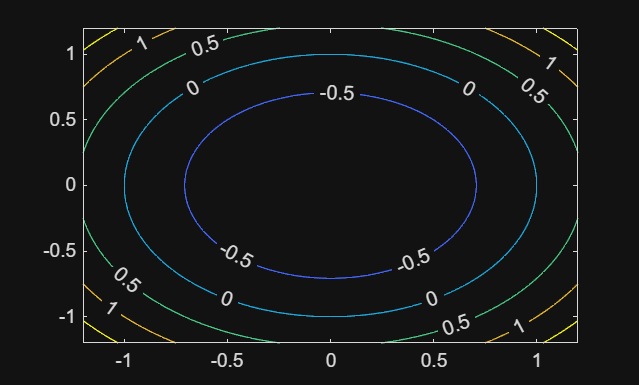

contour(xgrid,ygrid,z,'ShowText','off');

In this example, 0 is one of the values contour chooses automatically, but we can also specify the values we want.

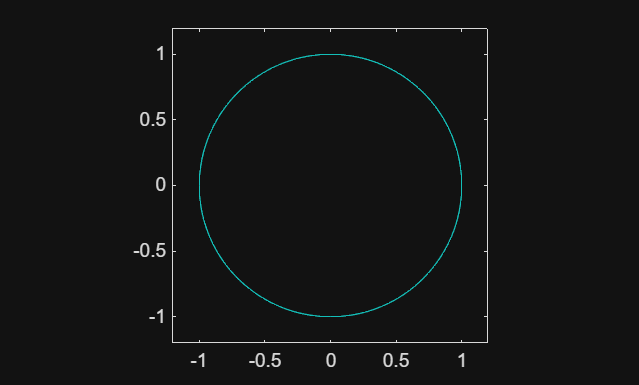

v = [0,0];    
contour(xgrid,ygrid,z,v);
axis('equal')

By specifying that the axes should be equal, we make it clearer that the results form a circle.

We can use **contoutraqrc** to compute the locations where $f(x,y)$is 0 and return them in an array.  The result, C, is a ContourArray, which stores the results, in a matrix, in a weird format.  To unpack the values in this matrix, we'll use [matrix indexing, which you should read about in this article](https://www.mathworks.com/company/newsletters/articles/matrix-indexing-in-matlab.html).

C = contourc(x,y,z,v)

错误使用 contourc
X 和 Y 的长度必须分别与 Z 中的列数和行数匹配。

level = C(1,1)
numxy = C(2,1)
xzero = C(1,2:end)
yzero = C(2,2:end)

Now xzero and yzero contain corresponding values of x and y where $f(x,y)$is 0, and we can plot them.

plot(xzero, yzero,'b.')

## Generalizing

There is no end to the functions of two variables that you can define. There is, however, a set of functions that show up again and again, and these are the quadratic functions of two variables. The general form (containing all possible quadratic, linear and constant terms) is


$$f(x,y) = A x^2+B x y + C y^2+D x + E y + F$$


where A,B,C,D,E,and F are arbitrary parameters, some of which may be zero. The curves defined by $f=0$ are called conic sections, and represent the intersection of a double cone and a plane. The non-degenerate cases include circles, parabolas, ellipses, and hyperbolas.

**Exercise 1**: Use **contour** to visualize solutions to the equation 


$$\frac{x^2}{a^2} + \frac{y^2}{b^2} - 1 = 0$$


for different values of **a** and **b**. What kind of curve do you get?  What features of the curve do $a$ and $b$ control?  Hint: Write a function called **myfunc2** that takes **x**, **y**, **a**, and **b** as input variables.  Use a for loop to plot contours for a range of values for **a**, with **b** held constant.

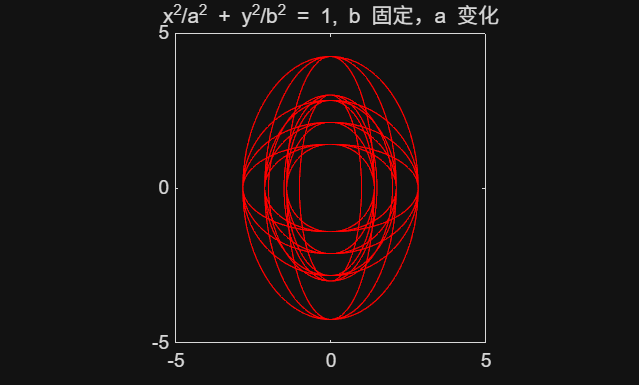

xaxis = linspace(-5,5,200);
yaxis = xaxis;
[X,Y] = meshgrid(xaxis, yaxis);

v = [1 1];
b = 3;                    % 固定 b
a_list = 1:0.5:2;         % 扫 a

newplot; hold on; axis equal; box on
for a = a_list
    Z = (X./a).^2 + (Y./b).^2;      % 或者 Z = myfunc2(X,Y,a,b)
    contour(X, Y, Z, v, 'r');       % 直接画 z=1 的等高线
end
title('x^2/a^2 + y^2/b^2 = 1, b 固定，a 变化')

function res = myfunc2(x,y,a,b)

res = x.^2./a.^2 + y.^2/b.^2 -1 
end



Use **contour** to visualize solutions to the equation 


$$\frac{x^2}{a^2} - \frac{y^2}{b^2} - 1 = 0$$
 

for different values of a and b. What kind of curve do you get?  What features of the curve do $a$ and $b$ control?

x = linspace(-10,10,200);
y = x;
[xgrid, ygrid] = meshgrid(x, y)

xgrid =   -10.0000   -9.8995   -9.7990   -9.6985   -9.5980   -9.4975   -9.3970   -9.2965   -9.1960   -9.0955   -8.9950   -8.8945   -8.7940   -8.6935   -8.5930   -8.4925   -8.3920   -8.2915   -8.1910   -8.0905   -7.9899   -7.8894   -7.7889   -7.6884   -7.5879   -7.4874   -7.3869   -7.2864   -7.1859   -7.0854   -6.9849   -6.8844   -6.7839   -6.6834   -6.5829   -6.4824   -6.3819   -6.2814   -6.1809   -6.0804   -5.9799   -5.8794   -5.7789   -5.6784   -5.5779   -5.4774   -5.3769   -5.2764   -5.1759   -5.0754
  -10.0000   -9.8995   -9.7990   -9.6985   -9.5980   -9.4975   -9.3970   -9.2965   -9.1960   -9.0955   -8.9950   -8.8945   -8.7940   -8.6935   -8.5930   -8.4925   -8.3920   -8.2915   -8.1910   -8.0905   -7.9899   -7.8894   -7.7889   -7.6884   -7.5879   -7.4874   -7.3869   -7.2864   -7.1859   -7.0854   -6.9849   -6.8844   -6.7839   -6.6834   -6.5829   -6.4824   -6.3819   -6.2814   -6.1809   -6.0804   -5.9799   -5.8794   -5.7789   -5.6784   -5.5779   -5.4774   -5.3769   -5.2764   -5.1759 

ygrid =   -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000
   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995 

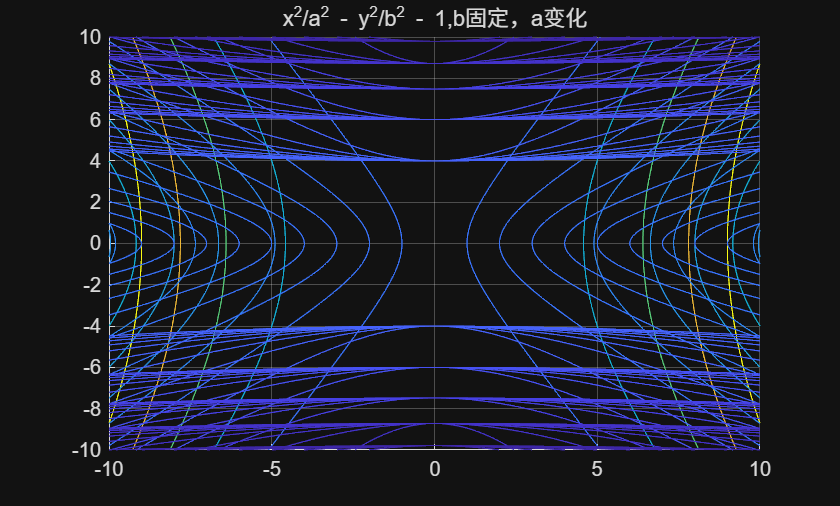

b = 2;
alpha = linspace(1,10,10);
figure; cla; hold on; grid on
for a = alpha;
    z = shuangqu(xgrid,ygrid,a,b);
    contour(xgrid,ygrid,z,'ShowText','off');
end
title('x^2/a^2 - y^2/b^2 - 1,b固定，a变化')

**Exercise 2**: Do some internet research to find out under what conditions the solutions of $f
$define an ellipse, a parabola, a hyperbola, or a circle. Visualize solutions for each of the conditions and confirm that they are correct.

function demo_conics
    % 网格
    x = linspace(-5,5,500);
    y = linspace(-5,5,500);
    [X,Y] = meshgrid(x,y);

    figure; tiledlayout(2,2);

    % 1 圆
    nexttile;
    plot_conic(X,Y, 1,0,1, 0,0,-1, 'Circle: x^2 + y^2 - 1 = 0');

    % 2 椭圆
    nexttile;
    plot_conic(X,Y, 0.25,0,1, 0,0,-1, 'Ellipse: x^2/4 + y^2 - 1 = 0');

    % 3 抛物线
    nexttile;
    plot_conic(X,Y, 1,0,0, 0,-2,0, 'Parabola: x^2 - 2y = 0');

    % 4 双曲线
    nexttile;
    plot_conic(X,Y, 1,0,-1, 0,0,-1, 'Hyperbola: x^2 - y^2 - 1 = 0');
end

function plot_conic(X,Y,A,B,C,D,E,F, ttl)
    Z = A*X.^2 + B*X.*Y + C*Y.^2 + D*X + E*Y + F;
    contour(X,Y,Z,[0 0],'LineWidth',1.2);
    axis equal tight; grid on;
    title(ttl);
end

## Function definitions

function res = myfunc1(x,y)
    % myfunc1   Computes f(x, y) = x^2 + y^2 -1
    res = x.^2 + y.^2 - 1;
end
function res = shuangqu(x,y,a,b)
    res = x.^2/a.^2 - y.^2/b.^2 - 1;
end